# Finite Impulse Response (FIR) Filtering

- firls [https://www.mathworks.com/help/signal/ref/firls.html](https://www.mathworks.com/help/signal/ref/firls.html) 

## Generate a kernel

sample_rate = 1024;
nyquist = sample_rate/2; % see nyquist theorem
band_pass = [20 45]; %the desired frequencies
transition = .1; %transition zone of filter
order = round(5*sample_rate/band_pass(1));
kernel_y = [0 0 1 1 0 0];
kernel_x = [0 band_pass(1)-band_pass(1)*transition band_pass(1) band_pass(2) band_pass(2)+band_pass(2)*transition nyquist];

## Plot the kernel

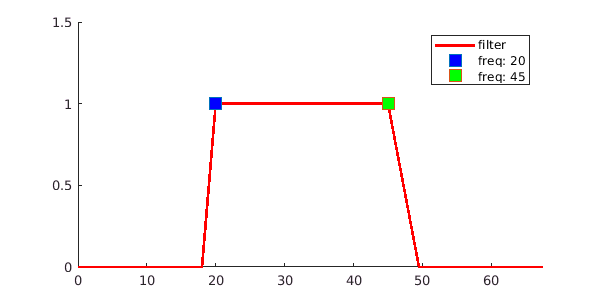

f1 = figure(1); clf;
f1.Position = [0 0 600 300];
hold on;
plot(kernel_x, kernel_y, 'r', 'linew', 2);
plot(band_pass(1), 1, 's', 'markerfacecolor', 'b', 'markersize', 12);
plot(band_pass(2), 1, 's', 'markerfacecolor', 'g', 'markersize', 12);
xlim([0 kernel_x(5)+kernel_x(2)]); %for centering
ylim([0 1.5]);
legend(["filter", "freq: " + num2str(band_pass(1)), "freq: " + num2str(band_pass(2))]);